**Load golf ball data**

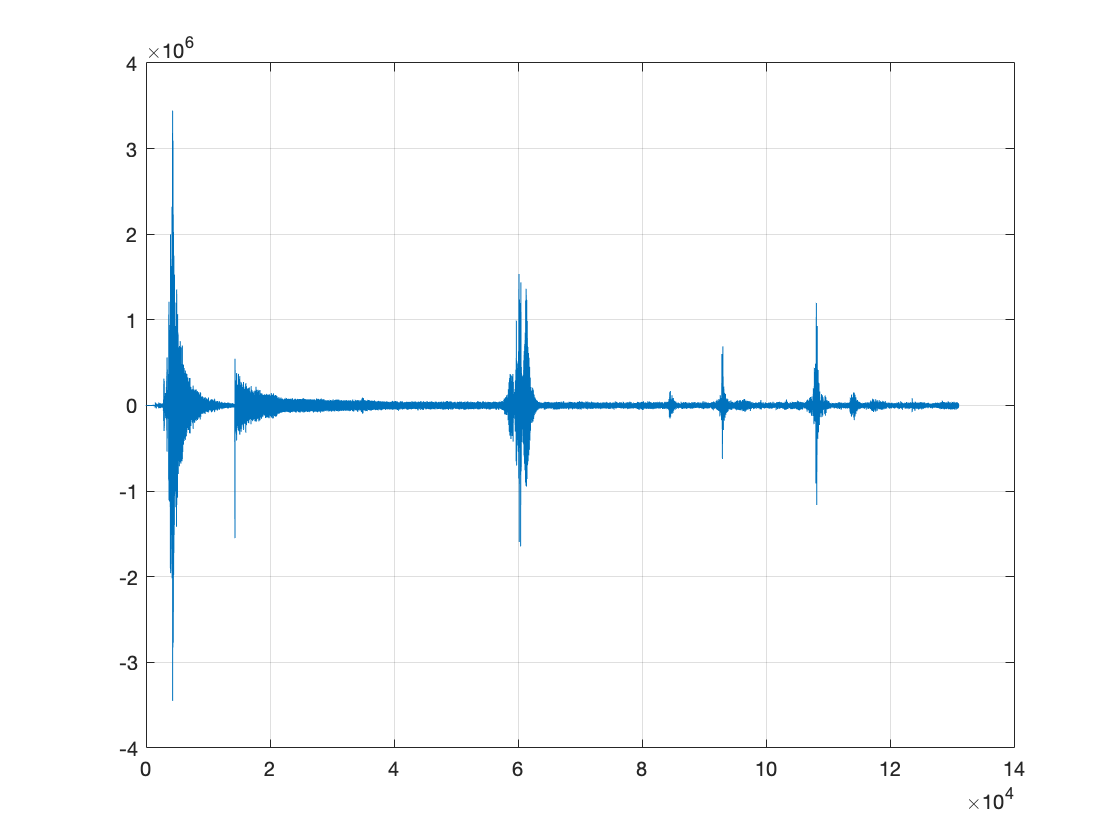

close all;
clear;

% Load golf shot data
filename = '7_iron_shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 2048; %FFT length
L = 90; %Window length
overlap = floor(0.85*L); % 50% overlap
N = 0; % User-defined. Used for adaptive threshold later.
w1 = kaiser(L,2.6);


**Signal data:**

% SIGNAL
signal = GolfBallData;
signal = signal((floor(0.15*fs)+1):floor(0.35*fs));

**Calling Spectrogram function:**

%Spectrogram 
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,w1,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames

**Adaptive threshold**

hist_length = floor(length(freq)/8); % Length hist = 1/8 of num. bins
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:length(freq)
       if frame(j) < threshold %If element in frame is less than threshold then set to 0
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Setting a target threshold:**

% % FOR DISPLAY:
% 
% for i = 1:nframes
%     frame = Spec_mag(:,i);
%     for j = 1:length(freq)
%        if frame(j) < 53
%            frame(j) = 20;
%        end
%     end
%     Spec_mag(:,i)=frame;
% end

**Peak tracking**

freq_at_peaks = zeros(1,nframes);
time_at_peaks = Spec_t;
amplitude = zeros(1,nframes);

for i = 1:nframes
    frame = Spec_mag(:,i); %Current time frame
    
    if max(frame) > 70
        
        %For curve fitting / peak tracking:
        index = find(frame == max(frame)); % Index used to find freq. at peak
        freq_at_peaks(i) = freq(index); % frequency at peak
        
        for j = (index-23):(index+23)
            amplitude(i) = amplitude(i) + 10^(frame(j)/20);
        end

    else
        time_at_peaks(i) = 0;
        
    end
end
freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);
amplitude = amplitude(amplitude ~= 0);


**Plotting Spectrogram:**

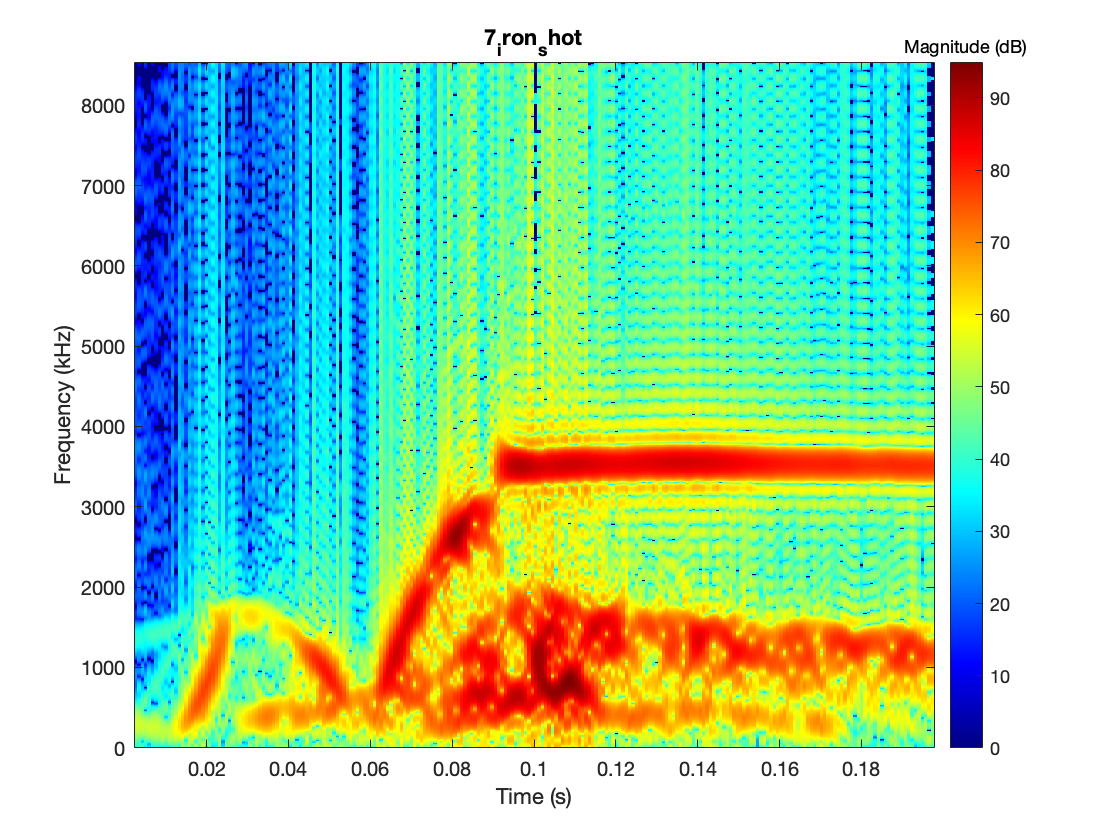

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("7_iron_shot"), xlabel("Time (s)"),ylabel("Frequency (kHz)")

**Plot at peaks:**

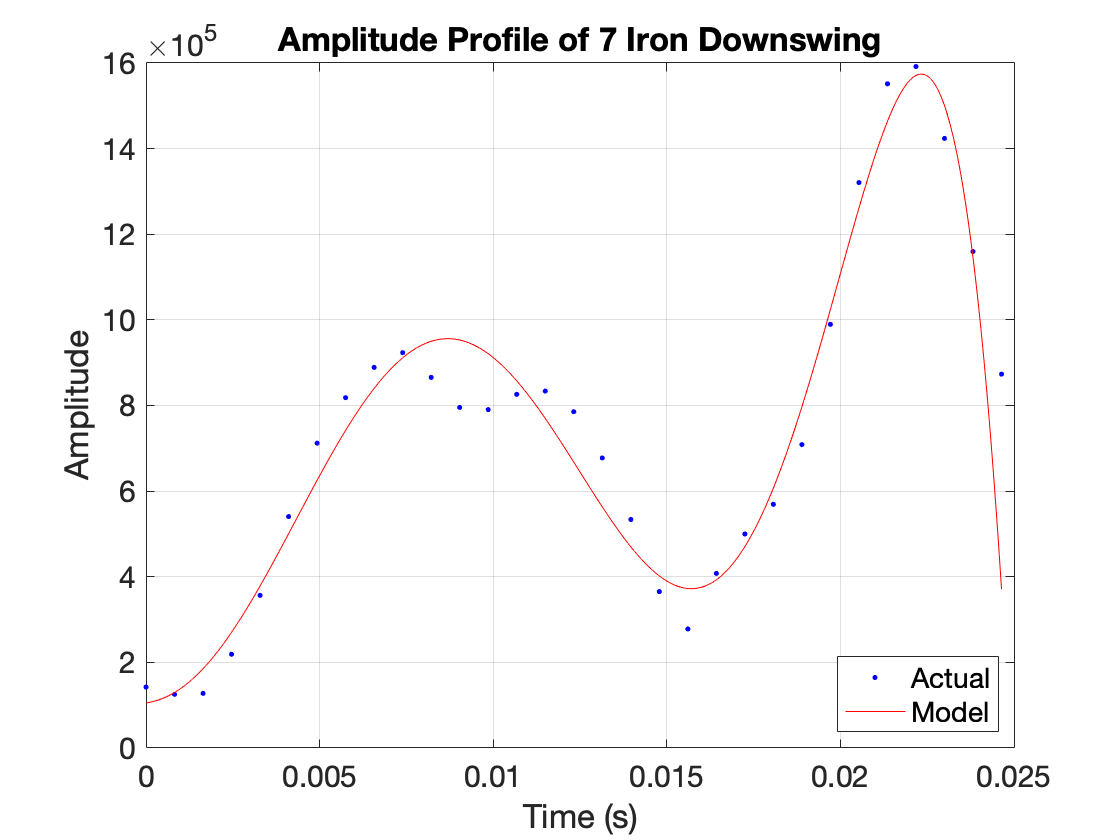


time_at_peaks = time_at_peaks(34:64); %downswing only
amplitude = amplitude(34:64);
time_at_peaks = time_at_peaks - time_at_peaks(1);
[fit, gof] = club_7_iron_amp_fit(time_at_peaks, amplitude);
set(gca,'FontSize',15);

%7 Iron
disp(fit);

     Linear model Poly6:
     fit(x) = p1*x^6 + p2*x^5 + p3*x^4 + p4*x^3 + p5*x^2 + 
                    p6*x + p7
       where x is normalized by mean 0.01232 and std 0.007468
     Coefficients (with 95% confidence bounds):
       p1 =  -1.661e+05  (-2.4e+05, -9.207e+04)
       p2 =  -4.608e+05  (-5.229e+05, -3.987e+05)
       p3 =   4.319e+05  (1.372e+05, 7.266e+05)
       p4 =   1.636e+06  (1.432e+06, 1.84e+06)
       p5 =  -1.034e+05  (-4.123e+05, 2.056e+05)
       p6 =  -9.591e+05  (-1.108e+06, -8.098e+05)
       p7 =   6.678e+05  (5.947e+05, 7.409e+05)



disp(gof);

           sse: 1.9310e+11
       rsquare: 0.9590
           dfe: 24
    adjrsquare: 0.9488
          rmse: 8.9699e+04



**Calculating mean error:**

%7 Iron club amp
model_at_peaks = feval(fit,time_at_peaks);
model_at_peaks = model_at_peaks.';
err = abs(model_at_peaks-amplitude);
mean_err = mean(err)

mean_err = 7.4126e+04